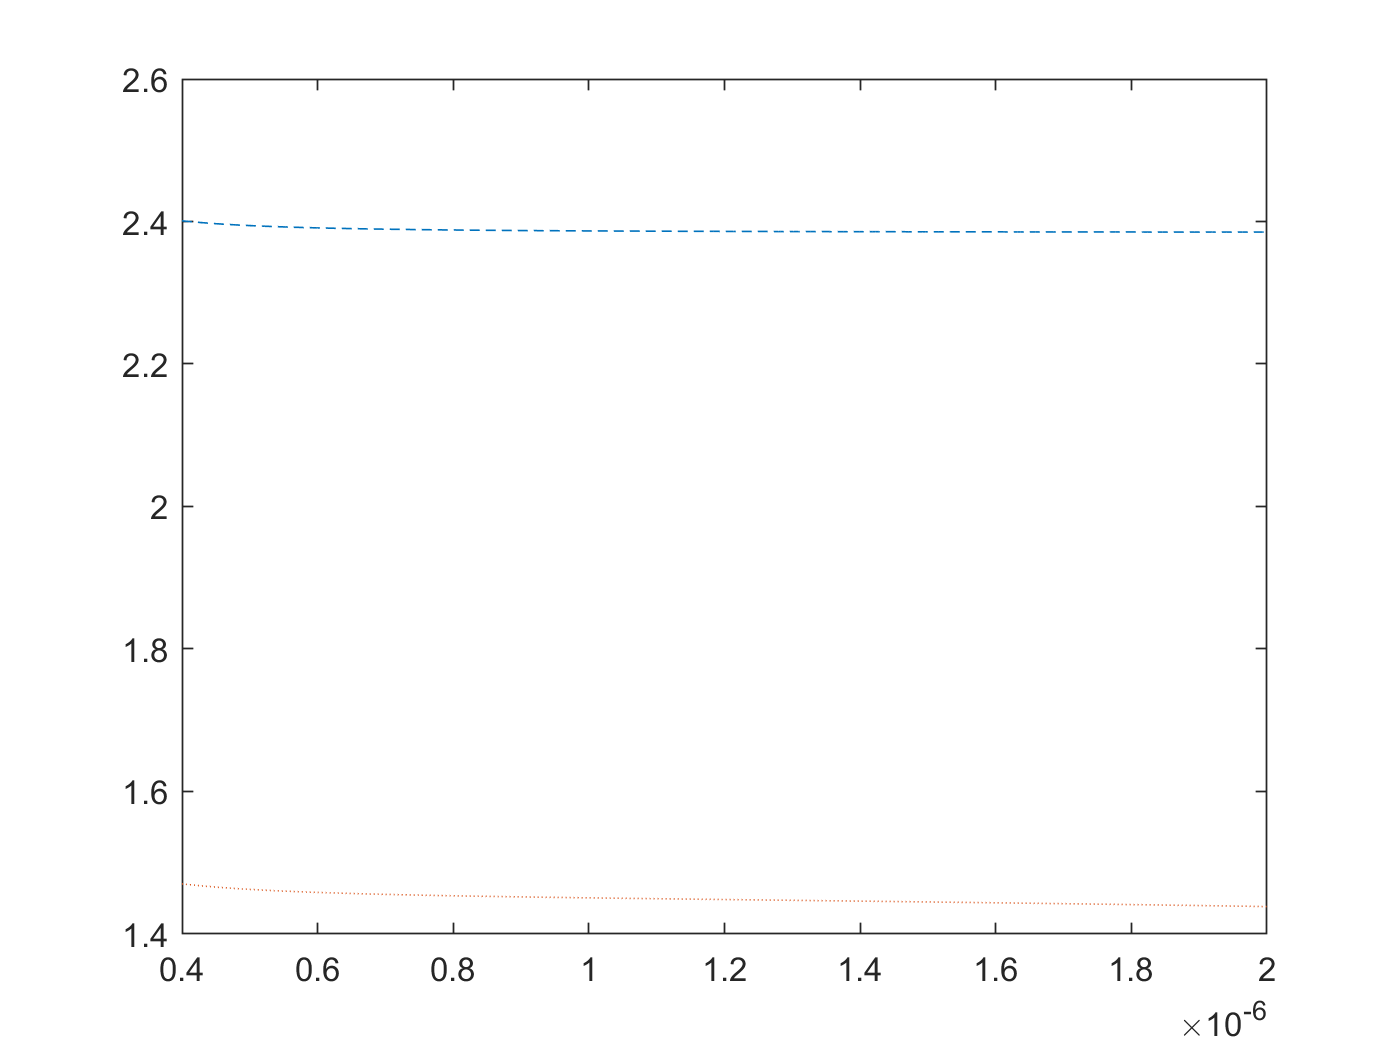

lambda1 = .4*10^(-6);
lambda2 = 2*10^(-6);
ts = .000001*10^(-6);

lambda = lambda1:ts:lambda2;
A1 = .696749;
A2 = .408218;
A3 = .890815;
B1 = .3306;
B2 = 4.3356;
C1S = .0690660*10^(-6);
C2S = .115662*10^(-6);
C3S = 9.900559*10^(-6);
C1D = .175*10^(-6);
C2D = .106*10^(-6);

n_SiO2 = sqrt(1+((A1*(lambda.^2))./(lambda.^2-C1S^2)+((A2*(lambda.^2))./(lambda.^2-C2S^2)))+((A3*(lambda.^2))./(lambda.^2-C3S^2)));
n_Diamond = sqrt(1+((B1*(lambda.^2))./(lambda.^2-C1D^2))+((B2*(lambda.^2))/(lambda.^2-C2D^2)));

plot(lambda,n_Diamond,'--',lambda,n_SiO2,':')